## **External Replication Model HCP in AOMIC **

## **Part 1**

This is Part 1 of the external replication of the Linear Regression Model built in the HCP that is then tested in the AOMIC. It creates a positive and negative NMA

for the AOMIC according to the Node-Measure Assignments in the HCP. 

Before running this script: 

- HCP_compute_coupling_measures

- run HCP_NMAs_whole_sample

**1) Create a cell that contains for each subject a vector of 8 predictors for each node **

for i = 1:567
    x = final_r_all_AOMIC_567_new{i,1};
    for j = 1:358
    Node_all_baseline_AOMIC_weighted_only{i,j} = x(j,:);
    end
end


**2) Create cell that contains information from all subjects and all coupling measures for all nodes seaparetely (567*8)**

% extract for each collumn die 8 rows from each row and put them together in a matrix (--> I need 567*8 Matrix for each Node)

n = size(Node_all_baseline_AOMIC_weighted_only,2);
All_Nodes_complete_baseline_AOMIC_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_AOMIC_weighted_only{j} = vertcat(Node_all_baseline_AOMIC_weighted_only{:,j});
end

2.1.) Fix Problems with Node 171 & Node 343

Convert all Isnan Values to 0 (so that the Code works) 

% Node 38 
all_values_171 = All_Nodes_complete_baseline_AOMIC_weighted_only{1,171};
all_values_171(isnan(all_values_171)) = 0;

All_Nodes_complete_baseline_AOMIC_weighted_only{1,171} = all_values_171;


% Node 58 
all_values_343 = All_Nodes_complete_baseline_AOMIC_weighted_only{1,343};
all_values_343(isnan(all_values_343)) = 0;

All_Nodes_complete_baseline_AOMIC_weighted_only{1,343} = all_values_343;

**3) Build a positive and a negative NMA according to the NMAs from the HCP **

Node-Measure Affiliation from HCP

best_performing_measure_per_node_pos_HCP_wei

best_performing_measure_per_node_pos_HCP_wei =      5     5     5     5     5     5     5     5     5     3     2     2     5     5     5     1     8     3     5     5     1     1     8     6     6     5     6     5     7     3     4     5     1     8     1     5     6     5     5     5     6     6     5     5     5     5     8     5     6     8



best_performing_measure_per_node_neg_HCP_wei 

best_performing_measure_per_node_neg_HCP_wei =      7     7     6     1     2     8     8     4     4     7     7     5     6     8     2     6     4     6     8     6     6     6     6     8     2     6     4     7     6     6     6     4     5     6     6     4     1     1     4     4     1     1     7     2     3     3     7     4     4     7


**4) Extract the coupling values for the positive NMA**

Best_case_scenario_r_values_pos_AOMIC = zeros(358,567)

Best_case_scenario_r_values_pos_AOMIC =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0   


for i = 1:358
    index = best_performing_measure_per_node_pos_HCP_wei(i);
    Best_scenario_node_values = All_Nodes_complete_baseline_AOMIC_weighted_only{1,i}(:,index);
    
    Best_case_scenario_r_values_pos_AOMIC(i,:) = Best_scenario_node_values';
end

Best_case_scenario_r_values_pos_AOMIC = Best_case_scenario_r_values_pos_AOMIC'

Best_case_scenario_r_values_pos_AOMIC =     0.0478   -0.1336    0.0659   -0.0517   -0.0143   -0.0460   -0.1341    0.0126    0.0402    0.0311    0.1790    0.0395    0.0821    0.1734    0.1705    0.5839    0.1909    0.4459   -0.0566   -0.0640    0.5705    0.4821    0.0408    0.0707   -0.0479    0.0583    0.3486   -0.1349    0.2555    0.4590    0.4181    0.1842    0.3757    0.0215    0.2371    0.0937    0.0405   -0.0067    0.2020    0.0034    0.2299    0.3351    0.1023    0.2686    0.2877    0.1134    0.2527   -0.0221    0.2122    0.1511
    0.0717   -0.0047    0.3988    0.0753    0.0355   -0.0328    0.0202    0.1793    0.1228    0.1064    0.2756    0.0127    0.3116   -0.1628    0.1970    0.3181    0.0788    0.3231    0.1971    0.0489    0.2442    0.3675    0.1004    0.3387    0.3040   -0.1466    0.4479   -0.1576    0.2843    0.2222    0.0896   -0.1367    0.1099    0.0072    0.1377    0.1365    0.3742    0.1959    0.2124    0.2063    0.2961    0.5037    0.0170    0.2209    0.1742    0.217

**5) Extract the coupling values for the negative NMA**

Best_case_scenario_r_values_neg_AOMIC = zeros(358,567)

Best_case_scenario_r_values_neg_AOMIC =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0   


for i = 1:358
    index = best_performing_measure_per_node_neg_HCP_wei(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_AOMIC_weighted_only{1,i}(:,index); 
    
    Best_case_scenario_r_values_neg_AOMIC(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_AOMIC = Best_case_scenario_r_values_neg_AOMIC'

Best_case_scenario_r_values_neg_AOMIC =     0.1837    0.0184    0.3176    0.3702    0.5439    0.3209    0.3426    0.3480    0.3681   -0.0179    0.0917    0.0993    0.3901    0.1109    0.3985    0.4251    0.4445    0.2414    0.1367    0.4019    0.3466    0.3115    0.1253    0.1390    0.1490    0.2018    0.3043    0.0765    0.3074    0.3052    0.3702   -0.1608   -0.0287    0.0772    0.0428    0.1455    0.0377    0.0645    0.3653    0.0436    0.0981    0.1619    0.0234    0.2539    0.2913    0.4138    0.1666    0.1530    0.3630   -0.0460
    0.2479    0.0148    0.5471    0.3962    0.4822    0.2871    0.2994    0.3788    0.4234   -0.0125    0.4596   -0.1684    0.4342    0.0209    0.3797    0.4037    0.2816    0.2423    0.1384    0.4244    0.3640    0.2373    0.2911    0.1167    0.1383    0.0155    0.2732    0.1293    0.3263   -0.0513    0.1814   -0.0002   -0.2628   -0.1319   -0.0470    0.1193    0.1927    0.2011    0.3535    0.1954    0.2106    0.3758    0.0752    0.2228    0.3563    0.353

## **Part 2**

This is Part 2 of the external replication of the Linear Regression Model built in the HCP that is then tested in the AOMIC. It creates the Linear Regression Model in the

HCP and tests for its prediction of cognitive ability scores in the AOMIC sample. 

**1) Build Model in HCP **

Assign the Behavioral Variables 

Intelligence_HCP = HCP_behavioral_1030.G_Factor;
ALter_HCP = HCP_behavioral_1030.Age;
Gender_HCP = HCP_behavioral_1030.("Gender num");
Motion_HCP = HCP_behavioral_1030.Mean_mean_FD;
Handedness_HCP = HCP_behavioral_1030.Handedness;

 Convert scores into z-scores

Alter_HCP_z = normalize(ALter_HCP);
Gender_HCP_z = normalize(Gender_HCP);
Motion_HCP_z = normalize(Motion_HCP);
Handedness_HCP_z = normalize(Handedness_HCP);

Intelligence_HCP_z = normalize(Intelligence_HCP);


 Regress out the confounding Variables from Intelligence

confounds = [Alter_HCP_z Gender_HCP_z Motion_HCP_z Handedness_HCP_z];

mdl_regress_HCP_intelligence = fitlm(confounds,Intelligence_HCP_z)

mdl_regress_HCP_intelligence = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate        SE         tStat         pValue  
                   _________    ________    __________    __________

    (Intercept)    5.211e-18     0.02966    1.7569e-16             1
    x1             -0.021919    0.030573      -0.71695       0.47357
    x2              -0.15877    0.030509        -5.204    2.3558e-07
    x3              -0.25463    0.029905       -8.5148    5.8729e-17
    x4             0.0095075    0.029823        0.3188       0.74995


Number of observations: 1030, Error degrees of freedom: 1025
Root Mean Squared Error: 0.952
R-squared: 0.0974,  Adjusted R-Squared: 0.0939
F-statistic vs. constant model: 27.6, p-val

residuals_intelligence_HCP_z = mdl_regress_HCP_intelligence.Residuals.Raw

residuals_intelligence_HCP_z =    -0.2073
   -0.8205
   -0.1730
    1.9859
   -1.0625
   -0.1999
   -0.7641
   -0.1122
    0.5758
    0.4516


Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_r_values_pos_HCP

Best_case_scenario_r_values_pos =    -0.1366   -0.3385   -0.0198   -0.1166   -0.1964   -0.4137   -0.4421   -0.0079   -0.1260    0.1991    0.1177    0.1546   -0.1378   -0.0291    0.1596    0.4241    0.1199    0.3447   -0.2335   -0.4357    0.5659    0.6289    0.1382    0.1798    0.0403    0.1020    0.2674   -0.1109    0.0797    0.2280    0.0762   -0.0273    0.1640    0.0657    0.2020   -0.2801    0.0800   -0.0040   -0.1488   -0.1797   -0.1110    0.1756   -0.1038   -0.0397    0.0403    0.0980    0.1806   -0.2014   -0.0008    0.0757
   -0.0681   -0.1245   -0.0492   -0.0583   -0.1196   -0.1415   -0.2524   -0.0424   -0.0311    0.1042    0.1040    0.1562   -0.1134   -0.0593    0.1231    0.4581    0.1123    0.3516   -0.2692   -0.1935    0.4701    0.5024    0.1312    0.0690    0.0465    0.1584    0.2626   -0.0633    0.0392    0.2135    0.2591   -0.0710    0.1461   -0.0380    0.2161   -0.0822    0.0622   -0.0365   -0.0974   -0.1442   -0.0264    0.2314   -0.0799   -0.0457    0.0825    0.0359    0

Best_case_scenario_r_values_neg = Best_case_scenario_r_values_neg_HCP

Best_case_scenario_r_values_neg =     0.0455    0.0015    0.0710    0.2584    0.4087    0.4004    0.3529    0.2731    0.2609    0.0121   -0.0988   -0.1664    0.0486    0.1038    0.2471    0.0137    0.2108   -0.0396    0.3000    0.1523    0.0618    0.0373   -0.0130   -0.1256    0.1460   -0.0015    0.2255   -0.0354    0.2853    0.0673    0.1450   -0.1154   -0.1546    0.1734    0.1927    0.3200    0.2397    0.0566    0.3179    0.2570    0.4095    0.3543   -0.0253    0.1680    0.2864    0.3011    0.0244    0.1257    0.2811    0.0416
    0.1003   -0.0166    0.1040    0.3000    0.3848    0.2603    0.3833    0.0845    0.1115   -0.0621    0.0554    0.0496    0.0517   -0.0137    0.2308    0.1022    0.0926    0.1457    0.2198    0.1640    0.1242    0.1670    0.0748    0.0916    0.1437    0.0427    0.2416    0.0013    0.0549    0.1034    0.1701    0.2602   -0.1183    0.1635    0.1518    0.0873    0.1911    0.0228    0.0658   -0.0045    0.2928    0.3529   -0.0129    0.1756    0.2000    0.3347   -0

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

 Regress out the confounding Variables from positive BCS 

confounds = [Alter_HCP_z Gender_HCP_z Motion_HCP_z Handedness_HCP_z];

mdl_regress_HCP_pos_bcs = fitlm(confounds,Positive_all)

mdl_regress_HCP_pos_bcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                    Estimate         SE         tStat         pValue  
                   ___________    ________    __________    __________

    (Intercept)    -1.3399e-15    0.028381    -4.721e-14             1
    x1                -0.11589    0.029254       -3.9615    7.9636e-05
    x2                -0.37224    0.029192       -12.751    1.1331e-34
    x3                 0.10747    0.028615        3.7558    0.00018249
    x4                 0.06198    0.028537         2.172      0.030087


Number of observations: 1030, Error degrees of freedom: 1025
Root Mean Squared Error: 0.911
R-squared: 0.174,  Adjusted R-Squared: 0.17
F-statistic vs. constant model: 53.8,

residuals_pos_HCP = mdl_regress_HCP_pos_bcs.Residuals.Raw

residuals_pos_HCP =    -1.9664
   -0.5252
    1.3083
   -0.5507
   -1.0371
    0.0781
   -1.7846
   -0.5018
   -0.2219
   -0.2787



mdl_regress_HCP_neg_bcs = fitlm(confounds,Negative_all)

mdl_regress_HCP_neg_bcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    ________    _________    __________

    (Intercept)    3.3068e-15    0.029473    1.122e-13             1
    x1               -0.15434     0.03038      -5.0803    4.4763e-07
    x2               -0.18202    0.030315      -6.0041    2.6676e-09
    x3                0.22854    0.029715       7.6908    3.4188e-14
    x4             -0.0041506    0.029634     -0.14006       0.88864


Number of observations: 1030, Error degrees of freedom: 1025
Root Mean Squared Error: 0.946
R-squared: 0.109,  Adjusted R-Squared: 0.105
F-statistic vs. constant model: 31.3, p-value = 1.

residuals_neg_HCP = mdl_regress_HCP_neg_bcs.Residuals.Raw

residuals_neg_HCP =    -1.1332
   -1.5687
   -0.0261
   -1.5364
   -0.7867
    1.9772
   -0.3045
    0.0136
    0.3145
   -0.9048


 Build the actual Model

Model_Matrix = [residuals_pos_HCP residuals_neg_HCP residuals_intelligence_HCP_z]

Model_Matrix =    -1.9664   -1.1332   -0.2073
   -0.5252   -1.5687   -0.8205
    1.3083   -0.0261   -0.1730
   -0.5507   -1.5364    1.9859
   -1.0371   -0.7867   -1.0625
    0.0781    1.9772   -0.1999
   -1.7846   -0.3045   -0.7641
   -0.5018    0.0136   -0.1122
   -0.2219    0.3145    0.5758
   -0.2787   -0.9048    0.4516


Model_Matrix = num2cell(Model_Matrix)

Model_Matrix = 1030×3 cell array
    {[-1.9664]}    {[-1.1332]}    {[-0.2073]}
    {[-0.5252]}    {[-1.5687]}    {[-0.8205]}
    {[ 1.3083]}    {[-0.0261]}    {[-0.1730]}
    {[-0.5507]}    {[-1.5364]}    {[ 1.9859]}
    {[-1.0371]}    {[-0.7867]}    {[-1.0625]}
    {[ 0.0781]}    {[ 1.9772]}    {[-0.1999]}
    {[-1.7846]}    {[-0.3045]}    {[-0.7641]}
    {[-0.5018]}    {[ 0.0136]}    {[-0.1122]}
    {[-0.2219]}    {[ 0.3145]}    {[ 0.5758]}
    {[-0.2787]}    {[-0.9048]}    {[ 0.4516]}
    {[ 1.6343]}    {[ 1.0555]}    {[ 0.4455]}
    {[-0.0164]}    {[-0.2156]}    {[-0.1642]}
    {[-1.3206]}    {[-0.4517]}    {[-0.0665]}
    {[ 1.3753]}    {[-0.6274]}    {[ 0.6445]}
    {[ 0.2361]}    {[-0.3230]}    {[-0.4087]}
    {[-0.9390]}    {[ 0.5542]}    {[-0.3895]}


Model_Matrix_table = cell2table(Model_Matrix)

Model_Matrix_table = 1030×3 table
    Model_Matrix1    Model_Matrix2    Model_Matrix3
    _____________    _____________    _____________

        -1.9664          -1.1332        -0.20731   
        -0.5252          -1.5687        -0.82047   
         1.3083        -0.026135        -0.17297   
       -0.55069          -1.5364          1.9859   
        -1.0371         -0.78673         -1.0625   
       0.078093           1.9772        -0.19988   
        -1.7846         -0.30455        -0.76406   
       -0.50179         0.013594         -0.1122   
       -0.22192          0.31447          0.5758   
       -0.27874         -0.90481         0.45162   
         1.6343           1.0555         0.44551   
      -0.016358         -0.21556        -0.16416   
        -1.3206         -0.45174        -0.06647   
         1.3753         -0.62737         0.64451   
         0.2361           -0.32

Model_Matrix_table.Properties.VariableNames = {'residuals_pos_bcs', 'residuals_neg_bcs','Residuals_intelligence'}

Model_Matrix_table = 1030×3 table
    residuals_pos_bcs    residuals_neg_bcs    Residuals_intelligence
    _________________    _________________    ______________________

          -1.9664              -1.1332               -0.20731       
          -0.5252              -1.5687               -0.82047       
           1.3083            -0.026135               -0.17297       
         -0.55069              -1.5364                 1.9859       
          -1.0371             -0.78673                -1.0625       
         0.078093               1.9772               -0.19988       
          -1.7846             -0.30455               -0.76406       
         -0.50179             0.013594                -0.1122       
         -0.22192              0.31447                 0.5758       
         -0.27874             -0.90481                0.45162       
           1.6343               1.0


mdl_pos_neg_bcs_HCP = fitlm(Model_Matrix_table)

mdl_pos_neg_bcs_HCP = Linear regression model:
    Residuals_intelligence ~ 1 + residuals_pos_bcs + residuals_neg_bcs

Estimated Coefficients:
                          Estimate         SE          tStat         pValue  
                         ___________    ________    ___________    __________

    (Intercept)          -8.2306e-18     0.02691    -3.0586e-16             1
    residuals_pos_bcs        0.44733    0.032169         13.906    2.1034e-40
    residuals_neg_bcs       -0.31038    0.030977        -10.019    1.3134e-22


Number of observations: 1030, Error degrees of freedom: 1027
Root Mean Squared Error: 0.864
R-squared: 0.175,  Adjusted R-Squared: 0.174
F-statistic vs. constant model: 109, p-value = 1.07e-43

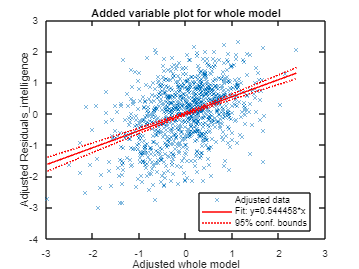

plot(mdl_pos_neg_bcs_HCP)

**2) Test Model in AOMIC **

Intelligence_AOMIC = AOMIC_behavioral_567_numerical.IST_intelligence_total

Intelligence_AOMIC =    159
   199
   270
   212
   172
   162
   267
   166
   267
   242


Alter_AOMIC = AOMIC_behavioral_567_numerical.age

Alter_AOMIC =    22.0000
   21.7500
   22.5000
   22.2500
   20.2500
   20.5000
   25.2500
   23.5000
   21.5000
   22.0000


Gender_AOMIC = AOMIC_behavioral_567_numerical.sex_num

Gender_AOMIC =      1
     1
     1
     0
     0
     1
     0
     0
     0
     0


Motion_AOMIC = AOMIC_behavioral_567_numerical.("Mean FD")

Motion_AOMIC =     0.1230
    0.1615
    0.1635
    0.0808
    0.1664
    0.1567
    0.1803
    0.0794
    0.1405
    0.0753


Handedness_AOMIC = AOMIC_behavioral_567_numerical.handedness_num

Handedness_AOMIC =      1
     1
     1
     1
     0
     1
     1
     1
     1
     0


Convert scores into z-scores

ALter_AOMIC_z = normalize(Alter_AOMIC);
Gender_AOMIC_z = normalize(Gender_AOMIC);
Motion_AOMIC_z = normalize(Motion_AOMIC);
Handedness_AOMIC_z = normalize(Handedness_AOMIC);

Intelligence_AOMIC_z = normalize(Intelligence_AOMIC);

 Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [ALter_AOMIC_z Gender_AOMIC_z Motion_AOMIC_z Handedness_AOMIC_z];
int_pred = predict(mdl_regress_HCP_intelligence,confounds)

int_pred =    -0.0789
   -0.3472
   -0.3704
    0.5333
   -0.0741
   -0.2971
   -0.2060
    0.5276
    0.1218
    0.5459



residuals_intelligence_AOMIC_z = (Intelligence_AOMIC_z - int_pred )

residuals_intelligence_AOMIC_z =    -1.0429
    0.2487
    2.0884
   -0.2992
   -0.7151
   -0.7480
    1.8472
   -1.4703
    1.5194
    0.4557


Retrieve NMAs 

Best_case_scenario_r_values_pos = Best_case_scenario_r_values_pos_AOMIC

Best_case_scenario_r_values_pos =     0.0478   -0.1336    0.0659   -0.0517   -0.0143   -0.0460   -0.1341    0.0126    0.0402    0.0311    0.1790    0.0395    0.0821    0.1734    0.1705    0.5839    0.1909    0.4459   -0.0566   -0.0640    0.5705    0.4821    0.0408    0.0707   -0.0479    0.0583    0.3486   -0.1349    0.2555    0.4590    0.4181    0.1842    0.3757    0.0215    0.2371    0.0937    0.0405   -0.0067    0.2020    0.0034    0.2299    0.3351    0.1023    0.2686    0.2877    0.1134    0.2527   -0.0221    0.2122    0.1511
    0.0717   -0.0047    0.3988    0.0753    0.0355   -0.0328    0.0202    0.1793    0.1228    0.1064    0.2756    0.0127    0.3116   -0.1628    0.1970    0.3181    0.0788    0.3231    0.1971    0.0489    0.2442    0.3675    0.1004    0.3387    0.3040   -0.1466    0.4479   -0.1576    0.2843    0.2222    0.0896   -0.1367    0.1099    0.0072    0.1377    0.1365    0.3742    0.1959    0.2124    0.2063    0.2961    0.5037    0.0170    0.2209    0.1742    0.2172    0


Best_case_scenario_r_values_neg = Best_case_scenario_r_values_neg_AOMIC

Best_case_scenario_r_values_neg =     0.1837    0.0184    0.3176    0.3702    0.5439    0.3209    0.3426    0.3480    0.3681   -0.0179    0.0917    0.0993    0.3901    0.1109    0.3985    0.4251    0.4445    0.2414    0.1367    0.4019    0.3466    0.3115    0.1253    0.1390    0.1490    0.2018    0.3043    0.0765    0.3074    0.3052    0.3702   -0.1608   -0.0287    0.0772    0.0428    0.1455    0.0377    0.0645    0.3653    0.0436    0.0981    0.1619    0.0234    0.2539    0.2913    0.4138    0.1666    0.1530    0.3630   -0.0460
    0.2479    0.0148    0.5471    0.3962    0.4822    0.2871    0.2994    0.3788    0.4234   -0.0125    0.4596   -0.1684    0.4342    0.0209    0.3797    0.4037    0.2816    0.2423    0.1384    0.4244    0.3640    0.2373    0.2911    0.1167    0.1383    0.0155    0.2732    0.1293    0.3263   -0.0513    0.1814   -0.0002   -0.2628   -0.1319   -0.0470    0.1193    0.1927    0.2011    0.3535    0.1954    0.2106    0.3758    0.0752    0.2228    0.3563    0.3532    0

Retrieve NMAs

Positive_all = nanmean(Best_case_scenario_r_values_pos,2)

Positive_all =     0.1508
    0.2098
    0.1978
    0.1654
    0.2501
    0.1771
    0.2191
    0.1880
    0.1834
    0.2198


Negative_all = nanmean(Best_case_scenario_r_values_neg,2)

Negative_all =     0.1803
    0.1917
    0.1788
    0.1597
    0.2211
    0.1723
    0.1982
    0.1624
    0.1865
    0.1833



Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_AOMIC_z Gender_AOMIC_z Motion_AOMIC_z Handedness_AOMIC_z];


Positive_all_pred = predict(mdl_regress_HCP_pos_bcs,confounds)

Positive_all_pred =    -0.2961
   -0.1648
   -0.2093
    0.3066
    0.5035
   -0.0955
    0.4015
    0.2185
    0.5346
    0.1151



residuals_pos = (Positive_all - Positive_all_pred)

residuals_pos =    -1.4763
    0.9898
    0.5037
   -1.4360
    2.0924
   -0.5185
    0.8317
   -0.3564
   -0.8724
    1.1494




Negative_all_pred = predict(mdl_regress_HCP_neg_bcs,confounds)

Negative_all_pred =    -0.1494
    0.1166
    0.0619
   -0.0745
    0.6585
    0.1974
    0.2871
   -0.1952
    0.3704
   -0.0742



residuals_neg = (Negative_all - Negative_all_pred)

residuals_neg =    -0.2670
   -0.0308
   -0.5435
   -1.2469
    0.7196
   -0.9668
    0.0845
   -1.0079
   -0.5169
   -0.2127


Xnew = [residuals_pos residuals_neg]

Xnew =    -1.4763   -0.2670
    0.9898   -0.0308
    0.5037   -0.5435
   -1.4360   -1.2469
    2.0924    0.7196
   -0.5185   -0.9668
    0.8317    0.0845
   -0.3564   -1.0079
   -0.8724   -0.5169
    1.1494   -0.2127


ypred = predict(mdl_pos_neg_bcs_HCP,Xnew)

ypred =    -0.5775
    0.4523
    0.3940
   -0.2554
    0.7126
    0.0681
    0.3458
    0.1534
   -0.2298
    0.5801


**3) Correlate predicted with observed scores**

[r,pval] = corr(ypred,residuals_intelligence_AOMIC_z)

r = 0.1926

pval = 3.8343e-06

***4) *****Plot the correlation **

sz = 25

sz = 25

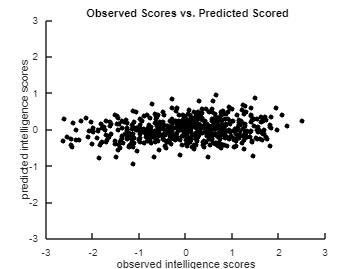


scatter(residuals_intelligence_AOMIC_z,ypred,sz,'filled', 'MarkerFaceColor','black')
title(' Observed Scores vs. Predicted Scored')
xlabel('observed intelligence scores')
ylabel('predicted intelligence scores')
xlim([-3,3])
ylim([-3,3])

% set(gca,'FontSize',25,'fontWeight','bold')